## Program_05_3

### Requirements

Write a script that will create 1,000 random resistors in batch 1 with a normal distribution, mean of 100 ohms, and standard deviation of 15 ohms. 

Perform the following operations with the resistor data using logical vectors where appropriate

- Output the total number of resistors created in batch 1 along with their actual mean and standard deviation as they will differ slightly from the values given.

- Find the positional number and corresponding resistance value for all resistors in the batch that fall above the upper bound of mean + 1 std or below the lower bound of mean - 1 std.

- Output the number of resistors rejected and the batch number.

- Output the position number and corresponding resistance value for all resistors rejected in the batch.

- If a batch has more than 1 rejected resistor all rejected resistors must be recreated using the randn function and used to replace the rejected resistorin the original vector of resistors.

- Repeat steps 2-5 until there are no resistors outside the lower and upper bounds.

### Program

In the code block below, create your program, editing the existing text as necessary.

**Tips:**

- "Repeat until some condition" should indicate to you that a while loop should be used.

- Recall that there is a function to find positional values.

- Utilize vectorized methods and logical vectors as much as possible to avoid overcomplicating your script.

- Keep in mind that the results will vary for each run of your code due to randomness. You can use the fact that about 1/3 of the values of each batch will be rejected as a way to determine if your output is reasonable.

**Note: **If you are using Octave then you will need to create a separate script file, save that separate file as the name **Program_05_03**. It will not conflict with this file of the same name since the extension will be different. 

% Program_05_3
% Author: Corey
% Assisted By: no one

% Program Description:
% This program creates 1,000 random resistors with a normal distribution
% and mean of 100 ohms and standard deviation of 15 ohms.

% Perform the following operations with the resistor data using logical
% vectors where appropriate.
% % Output of the title and author to the command window
fprintf('Output for Program_5_2 written by Corey.\n\n')

% 1. Output the total number of resistors created along with their actual 
%    mean and standard deviation as they will differ slightly from the 
%    values given.
fprintf('A total of 1000 resistors were created.\n\n')
Rmean = mean(Resistors);
fprintf('Actual Mean = %g ohms', Rmean)
Rstd = std(Resistors);
fprintf('\nActual standard deviation = %g ohms', Rstd)

% Output the position number and corresponding resistance value for all resistors rejected in the batch.

% 3. Output the position and resistance of resistors within +/- 1 Standard Deviation 
%    of the mean.
for sum
reject = abs(Resistors-Rmean) > Rstd; % logical vector for all resistors 
% within one standard deviation of the mean

reject = [find(Resistors(reject),Resistors(]; % resistors in this category
fprintf('\n\nResistors falling outside the mean +/- 1 Standard Deviation are Rejected\n\n\n')
b=1
fprintf('%g Resistors were rejected in Batch %g', sum(reject), b)
% If a batch has more than 1 rejected resistor all rejected resistors must be recreated using the randn
% function and used to replace the rejected resistorin the original vector of resistors.

% 4. Repeat step 3 for +/- 2 Standard Deviations and +/- 3 Standard
%    Deviations.
fprintf('\nPercentage of Resistors within + or - 2 Stdev of the mean = %g', Percent2std)
fprintf('\nPercentage of Resistors within + or - 3 Stdev of the mean = %g', Percent3std)

% 5. Output the resistor position numbers and the corresponding resistor 
%    values for all resistors outside of +/- 3 standard deviations of the mean
format compact;
fprintf('\n\nRejected Resistors: < mean-3*std or > mean+3*std\n\n')
Reject = abs(Resistors-Rmean)> 3*Rstd;
RejResistors = Resistors.*Reject;
find(RejResistors=0);
disp('      Resistor #    Resistor Value (Ohms)')



### Example Output

Your program output should match the following.

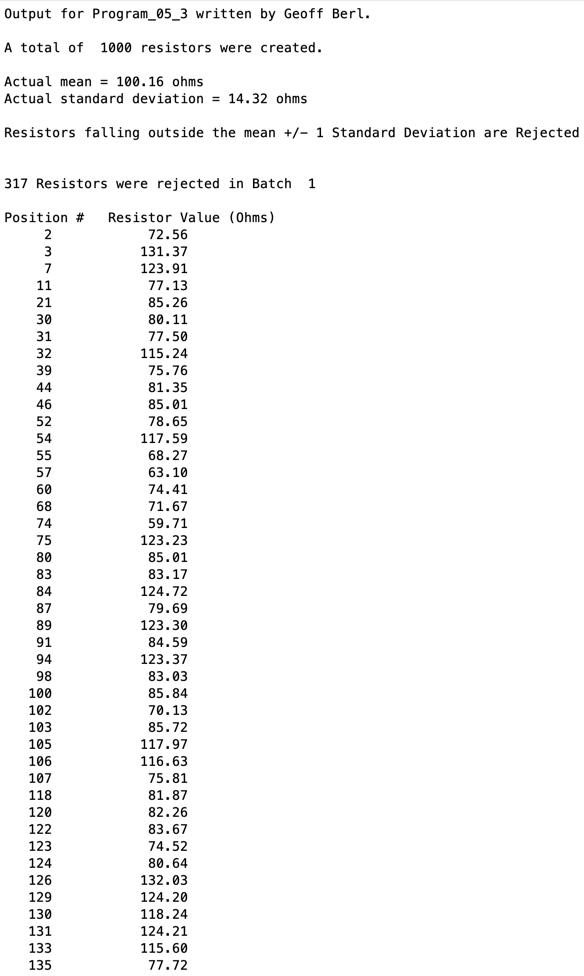

......

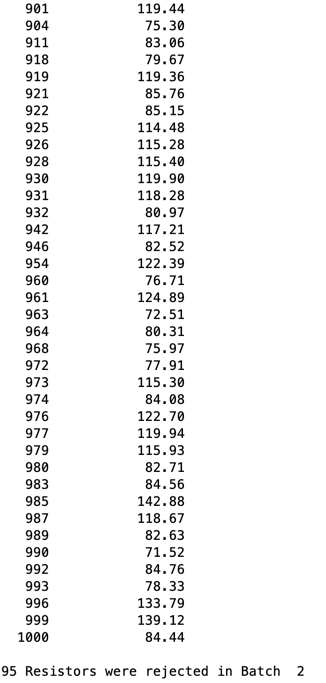

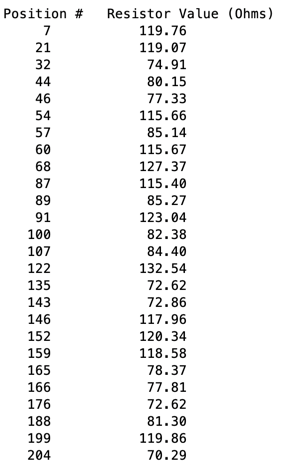

......

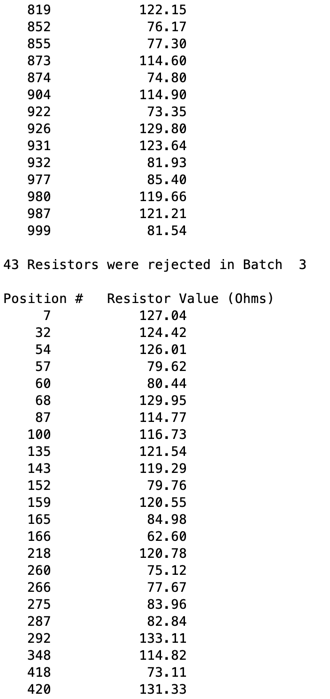

......